close all;
clear all;
clc;
A=imread('/Users/geethika/Desktop/dhoni.jpeg'); %reading image


X=double(rgb2gray(A));  % Convert RBG to gray, 256 bit to double.
nx = size(X,1)

nx = 448

ny = size(X,2) % storing size of

ny = 800

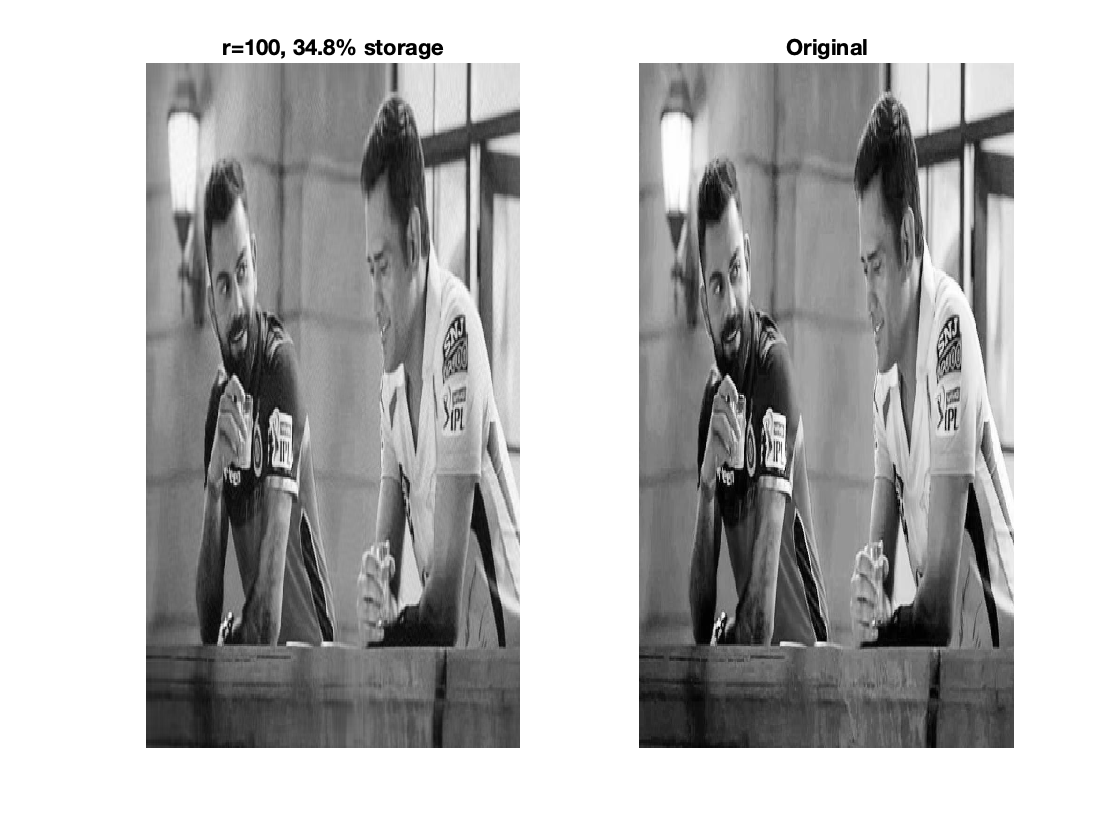

dispEr = [];
numSVals = [];
[U,S,V] = svd(X); % calculating Singular value decomposition
figure, subplot(1,2,2)
imagesc(X), axis off ,colormap gray %converting to grayscale
title('Original')
for r=1:1:100  % Truncation value
    Xapprox = U(:,1:r)*S(1:r,1:r)*V(:,1:r)'; % Approx. image
    subplot(1,2,1)
    imagesc(Xapprox), axis off
    title(['r=',num2str(r,'%d'),', ',num2str(100*r*(nx+ny)/(nx*ny),'%2.1f'),'% storage'])
    pause(0.0001);
    error=sum(sum((X-Xapprox).^2));% store vals for display
    dispEr = [dispEr; error];
    numSVals = [numSVals; r];
end

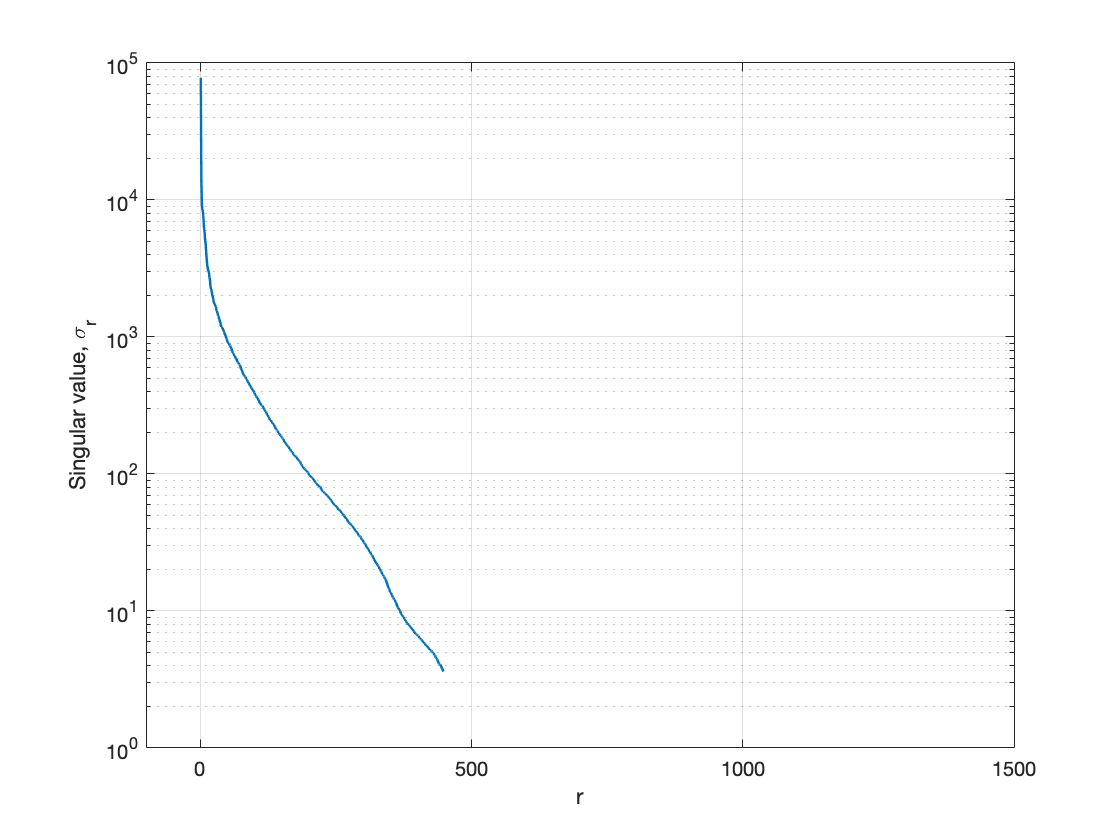

figure
semilogy(diag(S),'LineWidth',1.2), grid on
xlabel('r')
ylabel('Singular value, \sigma_r')
xlim([-100 1500])

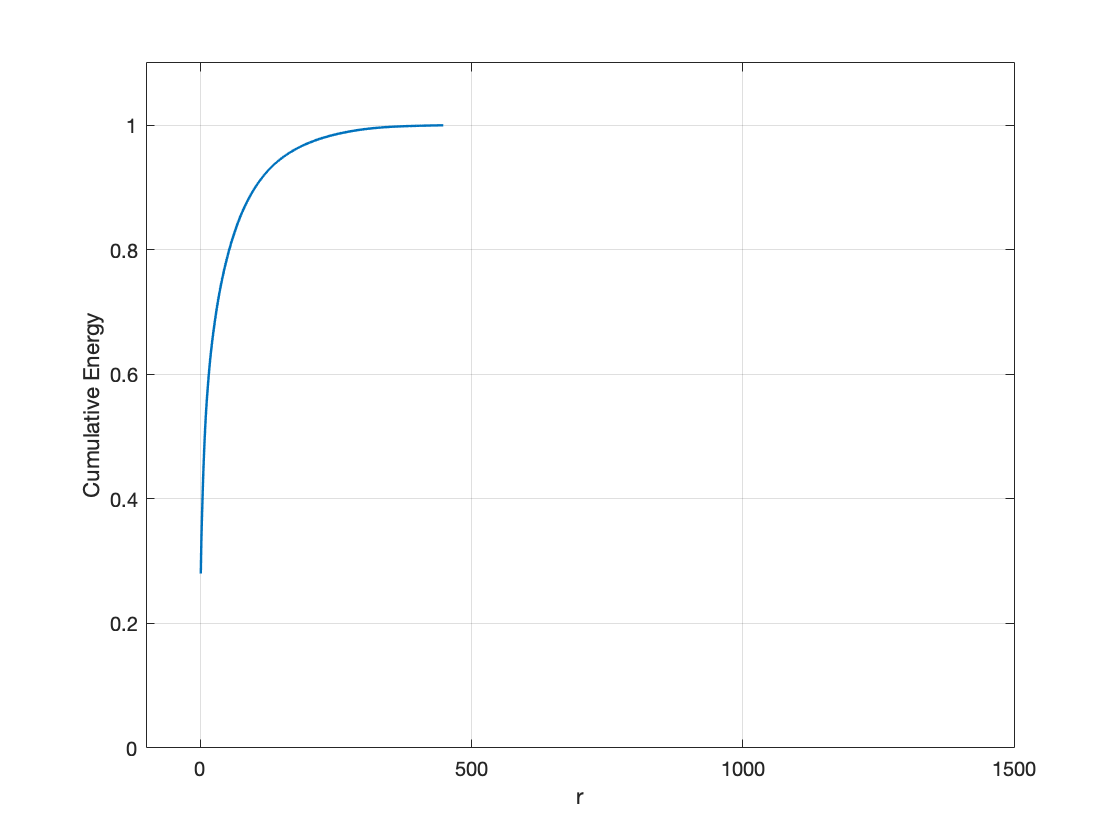

figure
plot(cumsum(diag(S))/sum(diag(S)),'LineWidth',1.2), grid on
xlabel('r')
ylabel('Cumulative Energy')
xlim([-100 1500]); ylim([0 1.1])

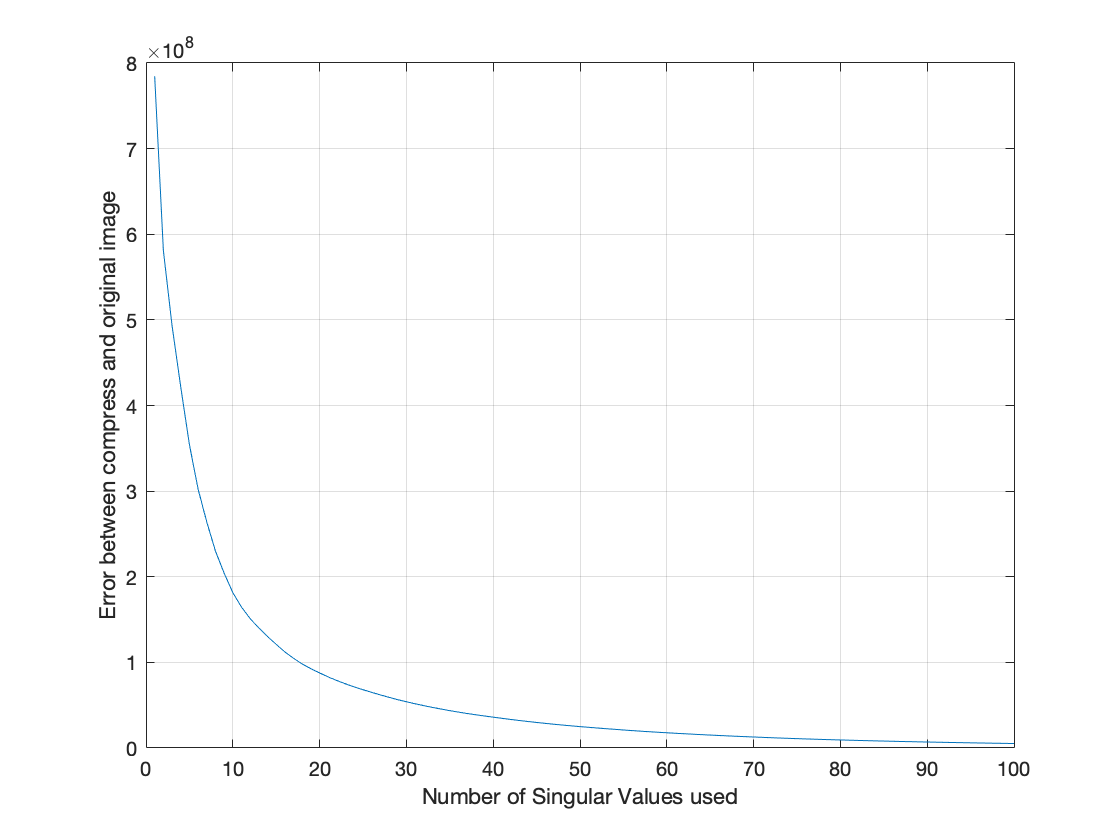

figure
title('Error in compression');
plot(numSVals, dispEr);
grid on
xlabel('Number of Singular Values used');
ylabel('Error between compress and original image');